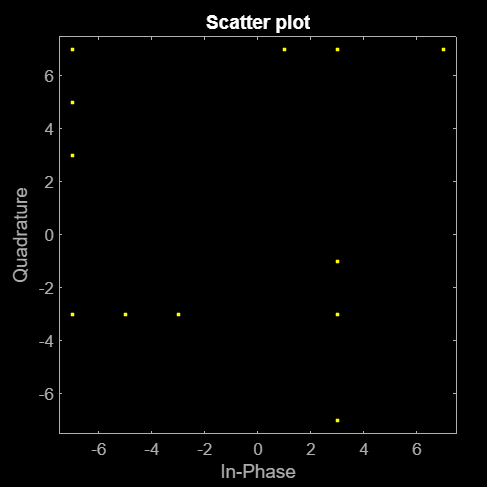

clear;
% data initialisation

size = 2*10^4;
data = rand([1, size]) * 100;
data_quant = floor(data);

Nbit = 7;
bin = de2bi(data_quant, Nbit, 'left-msb');

EncodeData  = zeros([size*Nbit*5, 1]);
for i = 1:size*Nbit
    EncodeData(1+5*(i-1)) = bin(i);
    EncodeData(2+5*(i-1)) = bin(i);
    EncodeData(3+5*(i-1)) = bin(i);
    EncodeData(4+5*(i-1)) = bin(i);
    EncodeData(5+5*(i-1)) = bin(i);
end
pad = [EncodeData; 0;0];



% Modulation - Introduce QAM-64 modulation
mod = qammod(pad, 64, 'InputType', 'bit');

% Plot the signal constellation
scatterplot(mod);

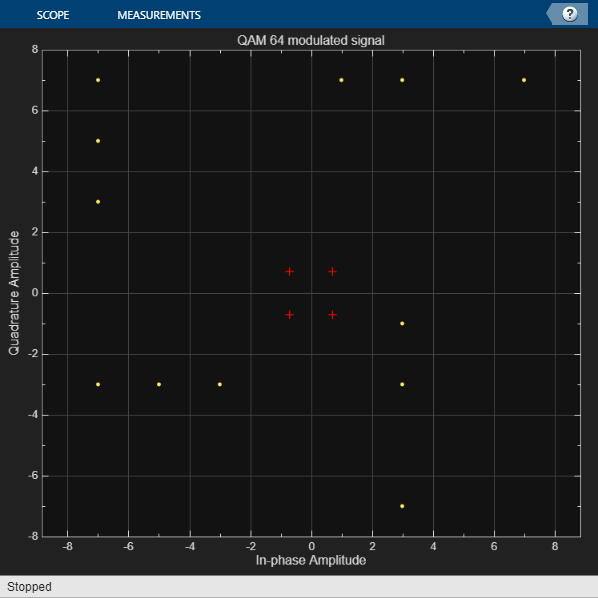

% Create a constellation diagram object
constDiagram = comm.ConstellationDiagram('SymbolsToDisplaySource', 'Property', 'Title', 'QAM 64 modulated signal','XLimits', [-8 8], 'YLimits', [-8 8]);

% Plot the constellation diagram
constDiagram(mod);
release(constDiagram);

% 2. Pulse shaping
rcTx = comm.RaisedCosineTransmitFilter(FilterSpanInSymbols=4, OutputSamplesPerSymbol=4);
txData = rcTx(mod);

Eb_N0_dB = 6; 
SNR = 10^(Eb_N0_dB/20); 
h = zeros(length(txData), 1); 

% Define path delays and path gains
path_delays = [0, 1, 3, 5, 7]; 
path_gains = [1, 0.7, 0.5, 0.3, 0.1]; 


for i = 1:length(path_delays)
    h = h + path_gains(i)*1/sqrt(2)*(randn(length(txData),1) + 1j*randn(length(txData),1)).*exp(-1j*2*pi*path_delays(i)/length(txData)*(1:length(txData))');
end


n = 1/sqrt(2)*(randn(length(txData),1) + 1j*randn(length(txData),1));


rxData = h.*txData + sqrt(1/SNR)*n;

% Generate random timing offset in the range [-0.5, 0.5] samples
timing_offset = rand() - 0.5;
rxData_shifted = circshift(rxData, round(timing_offset * length(rxData)));
rxData = rxData_shifted;

freq_offset = (rand() - 0.5) * 0.02; 
phase_shift = exp(1j * 2 * pi * freq_offset * (1:length(rxData))');
% Apply frequency offset to rxData
rxData_freq_offset = rxData .* phase_shift;
rxData = rxData_freq_offset;

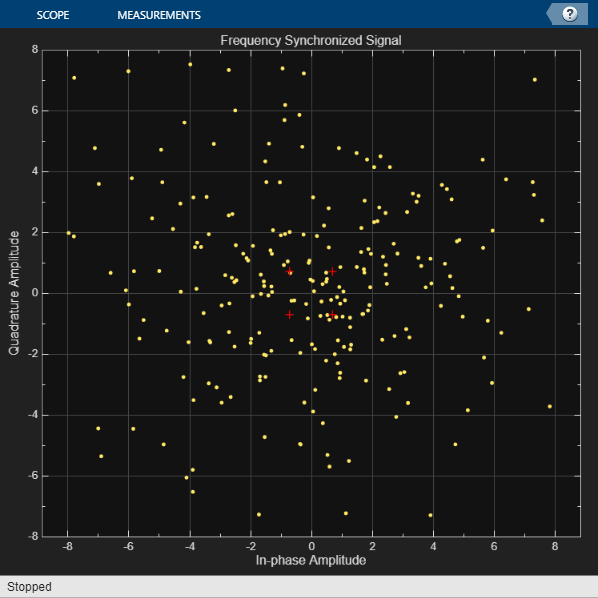

rxData_corrected = rxData ./ phase_shift;
rxData = rxData_corrected;
% Create a constellation diagram object
constDiagram = comm.ConstellationDiagram('SamplesPerSymbol', 4,'SymbolsToDisplaySource', 'Property', 'Title', 'Frequency Synchronized Signal','XLimits', [-8 8], 'YLimits', [-8 8]);

% Plot the constellation diagram
constDiagram(rxData);
release(constDiagram);

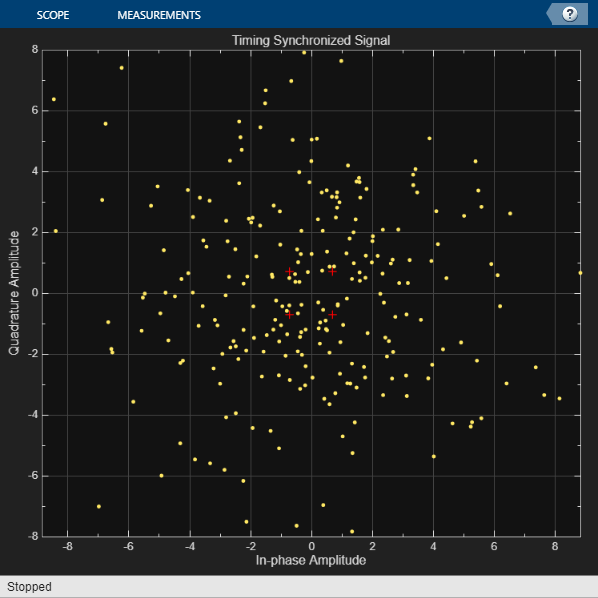

symbolSync = comm.SymbolSynchronizer('SamplesPerSymbol', 4);
rxData_corrected = step(symbolSync, rxData);
rxData = rxData_corrected;

% Create a constellation diagram object
constDiagram = comm.ConstellationDiagram('SamplesPerSymbol', 4,'SymbolsToDisplaySource', 'Property', 'Title', 'Timing Synchronized Signal','XLimits', [-8 8], 'YLimits', [-8 8]);

% Plot the constellation diagram
constDiagram(rxData);
release(constDiagram);

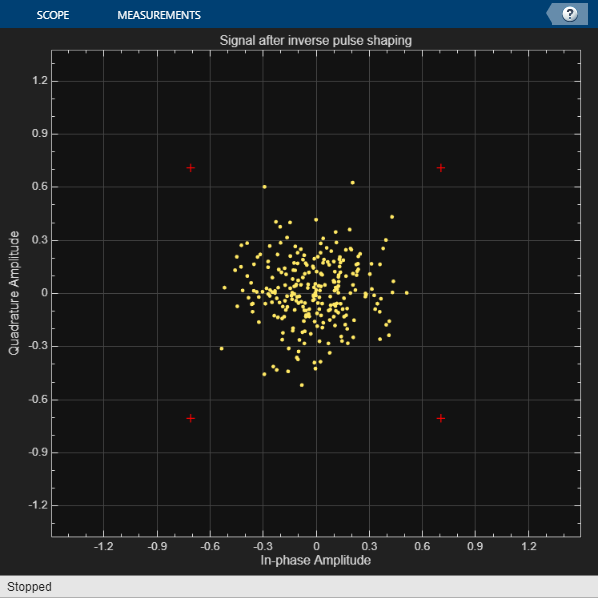

% Define the matched filter (inverse of the transmit filter)
rcRx = comm.RaisedCosineReceiveFilter('FilterSpanInSymbols', 4, 'InputSamplesPerSymbol', 4, 'DecimationFactor', 1);
rxData_matched_filter = rcRx(rxData);

% Adjust for group delay (delay caused by the filter)
group_delay = rcRx.FilterSpanInSymbols / 2;
rxData_matched_filter = rxData_matched_filter(group_delay+1:end);
% Adjust for filter gain
rxData_matched_filter = rxData_matched_filter / max(abs(rxData_matched_filter)); 
% Create a constellation diagram object
constDiagram = comm.ConstellationDiagram('SamplesPerSymbol', 4,'SymbolsToDisplaySource', 'Property', 'Title', 'Signal after inverse pulse shaping');

% Plot the constellation diagram
constDiagram(rxData_matched_filter);
release(constDiagram);

% Extract the relevant portion of the channel response (after symbol synchronization)
h_equalization = h(group_delay+1:group_delay+length(rxData_matched_filter));

% Zero-forcing channel equalization
rxData_equalized = rxData_matched_filter ./ h_equalization;
rxData = rxData_equalized;
constDiagram = comm.ConstellationDiagram('SamplesPerSymbol', 4,'SymbolsToDisplaySource', 'Property', 'Title', 'Channel equalization using zero forcing');

% Plot the constellation diagram
constDiagram(rxData);
release(constDiagram);

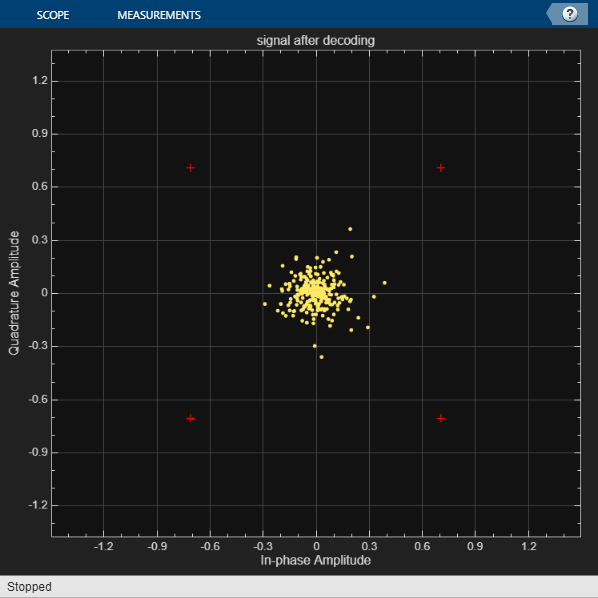

num_subframes = floor(length(rxData) / 5);
decoded_data = zeros(num_subframes, 1);

for i = 1:num_subframes
    subframe = rxData(5*(i-1) + 1 : 5*i);
    major_bit = mode(subframe);
    % Replace all bits in the sub-frame with the majorly occurring bit
    decoded_data(i) = major_bit;
end

% Concatenate the decoded sub-frames to get the final decoded data
decoded_data = reshape(decoded_data, [], 1);
constDiagram = comm.ConstellationDiagram('SamplesPerSymbol', 4,'SymbolsToDisplaySource', 'Property', 'Title', 'signal after decoding');

% Plot the constellation diagram
constDiagram(decoded_data);
release(constDiagram);

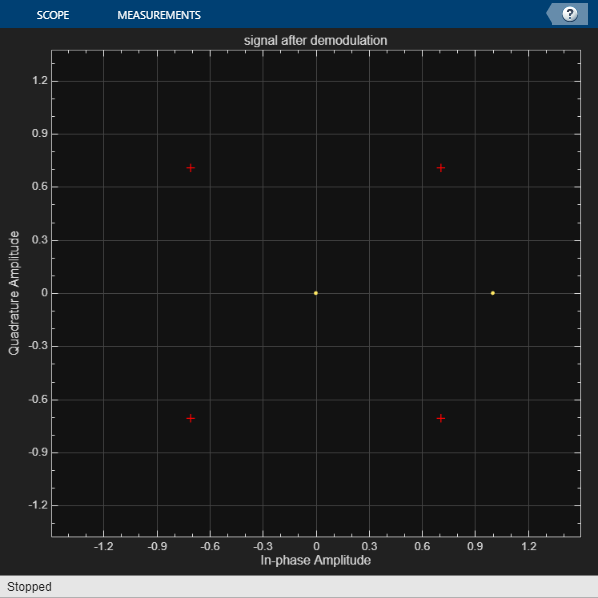

% Demodulate using qamdemod with QAM-64 modulation
demodulated_data = qamdemod(decoded_data, 64, 'OutputType', 'bit');
% Reshape the demodulated data to match the original bin size
demodulated_data = reshape(demodulated_data, [], 1);

constDiagram = comm.ConstellationDiagram('SamplesPerSymbol', 4,'SymbolsToDisplaySource', 'Property', 'Title', 'signal after demodulation');

% Plot the constellation diagram
constDiagram(demodulated_data);
release(constDiagram);

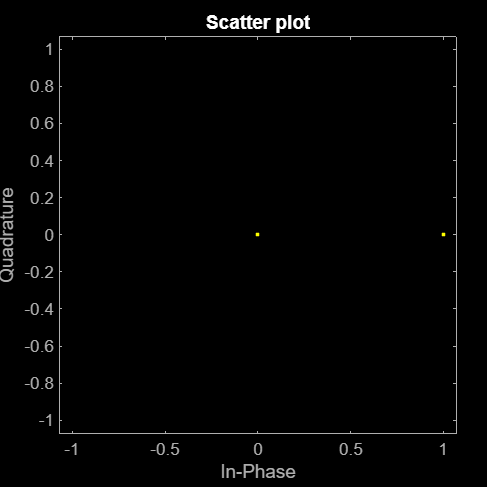

scatterplot(demodulated_data)

bin = reshape(bin, [], 1);
if length(demodulated_data) > 140000
    % Truncate demodulated_data to 140000 bits
    reference_length = length(bin);
    demodulated_data = demodulated_data(1:140000);
else
    % Pad demodulated_data with zeros if needed (original code)
    reference_length = length(bin);
    demod_length = length(demodulated_data);
    padding_size = max(0, reference_length - demod_length);
    demodulated_data = [demodulated_data; zeros(padding_size, 1)];
end
bit_errors = sum(demodulated_data ~= bin);

% Calculate bit error rate (BER)
ber = bit_errors / reference_length;

fprintf('\nBER = %d',ber)


BER = 5.007143e-01

fprintf('\nBit errors = %d',bit_errors)


Bit errors = 70100